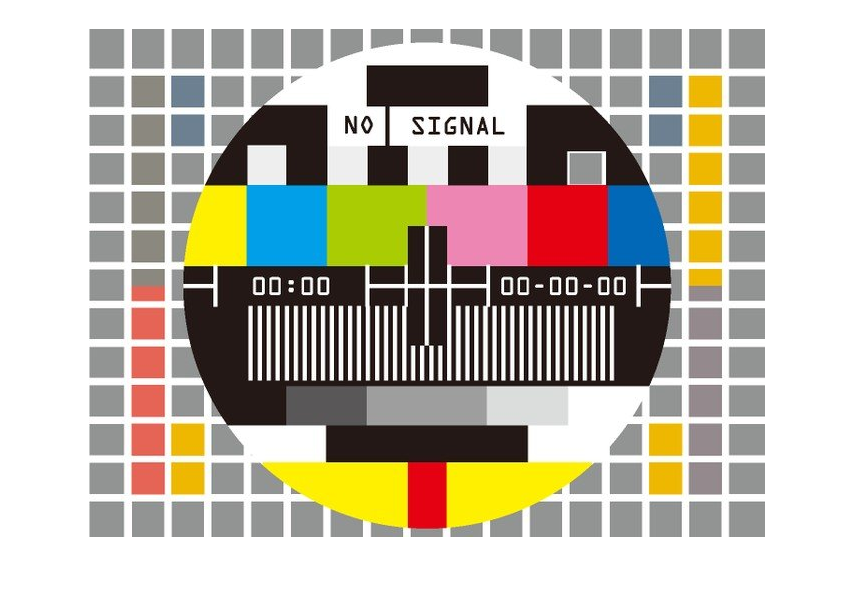

serializer1 = ImageSerializer('TestImages\tvTestScreen.jpg');
imshow(serializer1.rgb);

byteSignal = serializer1.GenerateRGBByteStream();
bitSignal = serializer1.GenerateRGBBitStream();


%insert Kanal here


deserializer = ImageDeserializer();
img = deserializer.GetImageFromBitVector(bitSignal);



%This is how to get the Demension of the matrix
lengt_bi = bitSignal(1,[end-31:end]);
len_x = bi2de(lengt_bi);
len_y = (length(bitSignal(1,[1:end-32]))/8)/len_x;